# Lab 3 

**Ashkan Jafari -- 810197483**

## Lab#3

### 1.

First of all, I designed my filter and export it as mat file inorder to load it in future.

load('lp_filter.mat')
N = 4096;
process = randn(N,1);
filtered_output = conv(process, lp_filter,"same");

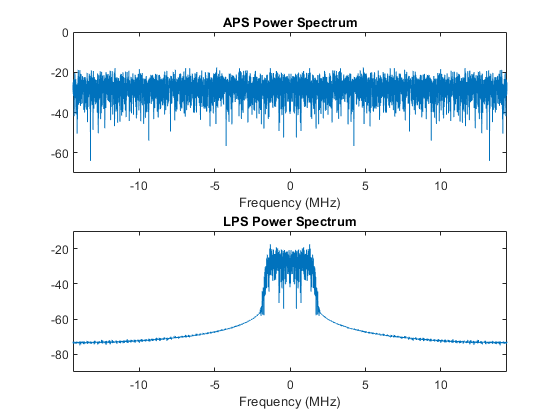

fs = 28.8e6;
n_fft = 4096;
%
[s, freq] = spectral_density(process,fs,n_fft);
subplot(2,1,1)
plot(freq/1e6, s)
title('APS Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-70 0])
xlim([-fs/2/1e6 fs/2/1e6])
%
[s, freq] = spectral_density(filtered_output,fs,n_fft);
subplot(2,1,2)
plot(freq/1e6, s)
title('LPS Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-90 -10])
xlim([-fs/2/1e6 fs/2/1e6])

time_power_original = t_power(process)

time_power_original = 1.0085

time_power_filter_out = t_power(filtered_output)

time_power_filter_out = 0.1134

BW_noise = noisebw(lp_filter,1,length(lp_filter),fs)

BW_noise = 3.3081e+06

BW_ratio = BW_noise/fs

BW_ratio = 0.1149

power_ratio = time_power_filter_out/time_power_original

power_ratio = 0.1125

As our signal is a white noise with P = 1 and therefore it's spectrum is uniformed then the below equation will be correct:


$$\frac{P_{filtered}}{P_{N}} \approx \frac{BW_{filtered}}{BW_N}$$


### 2.

%
fc = 3.57e6;
modulated_signal = modulation(filtered_output,fc,fs);
time_power_original = t_power(process)

time_power_original = 1.0085

time_power_filter_out = t_power(filtered_output)

time_power_filter_out = 0.1134

time_power_mod = t_power(modulated_signal)

time_power_mod = 0.0567

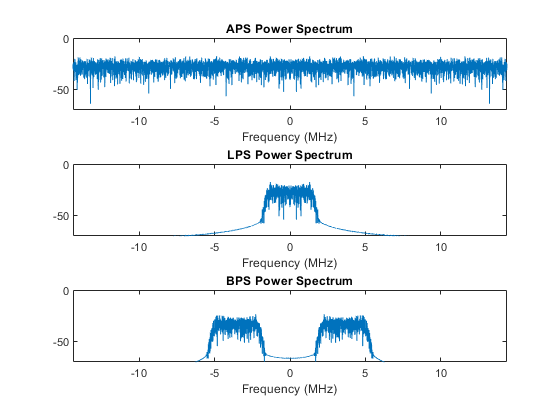

%
figure
[s, freq] = spectral_density(process,fs,n_fft);
subplot(3,1,1)
plot(freq/1e6, s)
title('APS Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-70 0])
xlim([-fs/2/1e6 fs/2/1e6])
%
[s, freq] = spectral_density(filtered_output,fs,n_fft);
subplot(3,1,2)
plot(freq/1e6, s)
title('LPS Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-70 0])
xlim([-fs/2/1e6 fs/2/1e6])
%
[s, freq] = spectral_density(modulated_signal,fs,n_fft);
subplot(3,1,3)
plot(freq/1e6, s)
title('BPS Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-70 0])
xlim([-fs/2/1e6 fs/2/1e6])

### 3.

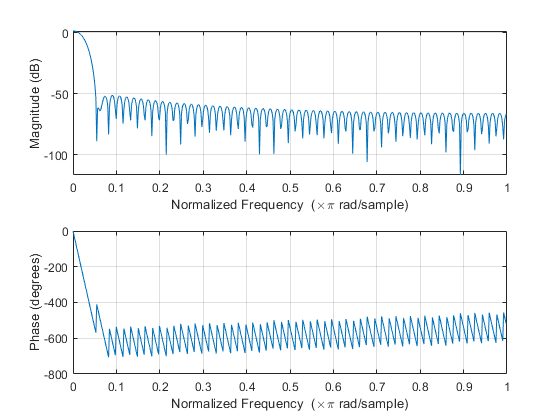

% BW = 0.7 MHz
lp_filter1 = fir1(120,[1/fs (0.7e6)/fs]);
freqz(lp_filter1)

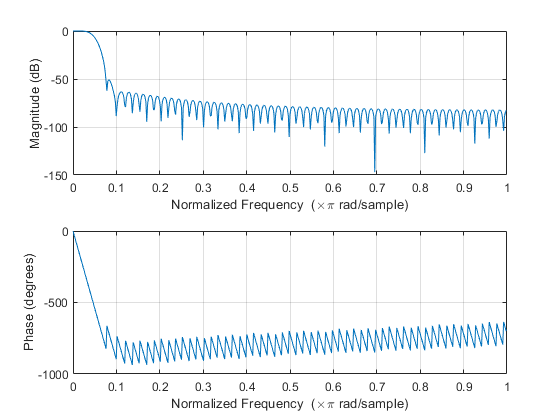

% BW = 1.4 MHz
lp_filter2 = fir1(120,[1/fs (1.4e6)/fs]);
freqz(lp_filter2)

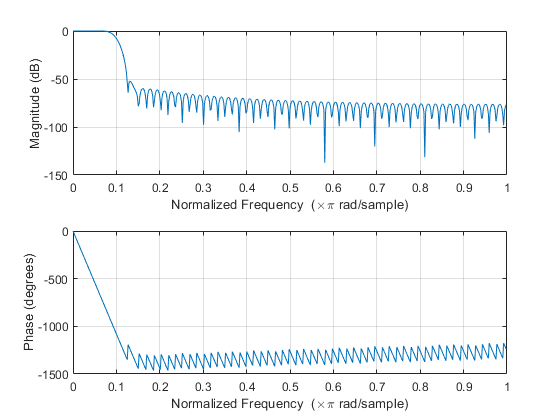

% BW = 2.8 MHz
lp_filter3 = fir1(120,[1/fs (2.8e6)/fs]);
freqz(lp_filter3)

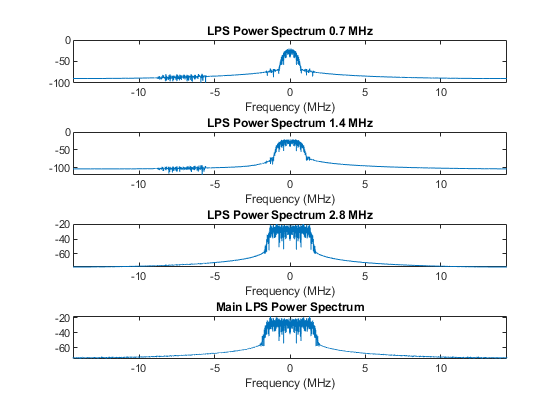

filtered1 = demodulation(modulated_signal, fc, fs, lp_filter1);
filtered2 = demodulation(modulated_signal, fc, fs, lp_filter2);
filtered3 = demodulation(modulated_signal, fc, fs, lp_filter3);
%
figure
[s, freq] = spectral_density(filtered1,fs,n_fft);
subplot(4,1,1)
plot(freq/1e6, s)
title('LPS Power Spectrum 0.7 MHz')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])
%
[s, freq] = spectral_density(filtered2,fs,n_fft);
subplot(4,1,2)
plot(freq/1e6, s)
title('LPS Power Spectrum 1.4 MHz')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])
%
[s, freq] = spectral_density(filtered3,fs,n_fft);
subplot(4,1,3)
plot(freq/1e6, s)
title('LPS Power Spectrum 2.8 MHz')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])
%
[s, freq] = spectral_density(filtered_output,fs,n_fft);
subplot(4,1,4)
plot(freq/1e6, s)
title('Main LPS Power Spectrum')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])

xLP_power = t_power(filtered_output)

xLP_power = 0.1134

xLP_1_power = t_power(filtered1)

xLP_1_power = 0.0268

xLP_2_power = t_power(filtered2)

xLP_2_power = 0.0456

xLP_3_power = t_power(filtered3)

xLP_3_power = 0.0975

As it is shown in the figures, the more we increase BW of filter, the more similar our output signal will be to the first input signal.

Similarly As BW is increased, there will be more frequency element which will be passed and consequently the energy will be increased. but this relation is not linear as the first relation I said.

### Functions:

function [spect, freq] = spectral_density(x, fs, n_fft)
freq = (0:n_fft-1)/n_fft * fs - fs/2;
Xf = fftshift(fft(x, n_fft))/n_fft;
R = 50;
spect =  10 * log10(abs(Xf).^2/(2*R)) + 30;  
end

function p = t_power(x)
p = sum(abs(x).^2)/length(x);
end

function z = modulation(x, fc,fs)
n = transpose(0:1/fs:(length(x)-1)/fs);
z = x .* cos(2*pi*fc*n);
end

function x_l = demodulation(x, fc, fs, lp_filter)
n = transpose(0:1/fs:(length(x)-1)/fs);
x_i = 2 * conv(x .* cos(2 * pi * fc * n), lp_filter,"same");
x_q = 2 * conv(x .* -sin(2 * pi * fc * n), lp_filter,"same");
x_l = x_i + 1j * x_q;
end